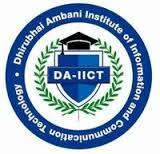

# CT303: Digital Communication

# Lab 5

## **Akshar Panchani**

## **202101522**

11-11-23

# Question 2-1

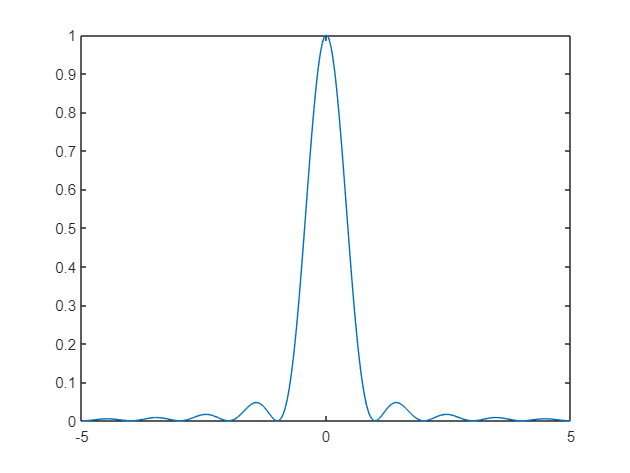

echo on
T=1;
delt_f=1 /(100*T);
f=- 5/T :delt_f:5/T;
sigma_a=1;
Sv=sigma_a^2*sinc(f*T).^2;

plot(f,Sv);

# Question 2-2

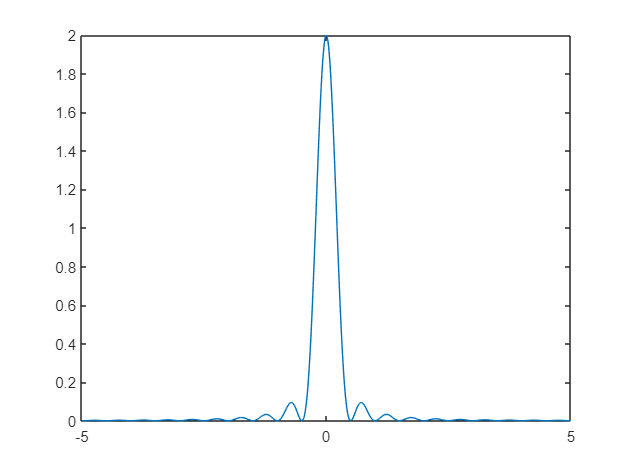

% MATLAB script for Illustrative Problem 6.2.
echo on
T=1;
delt_f=1 /(100*T);
f=-5/T:delt_f:5/T;
Sv=2*(cos(pi*f*T).*sinc(f*T)).^2;
% Plotting command follows.
plot(f,Sv); 

# Question 3-1

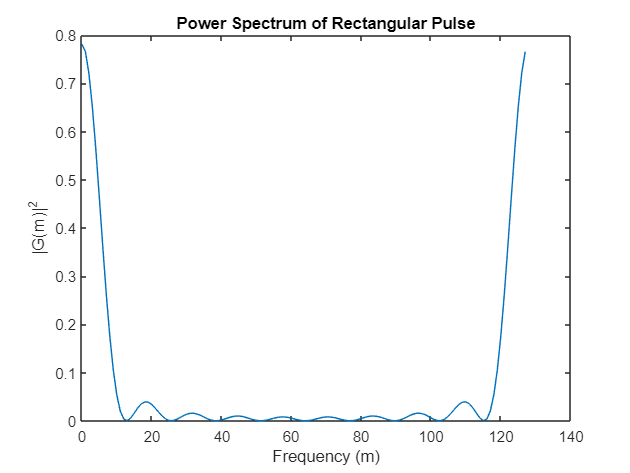

T = 1; % Pulse width
Nos = 128; % Number of samples
t = (0:Nos-1) / 10; % Time values from 0 to 12.7
g = rectpuls(t - T/2, T);
G = fft(g);
Sv = abs(G).^2 / Nos;
m = 0:Nos-1;
plot(m, Sv);
title('Rectangular Pulse power spectrum');
xlabel('Frequency m');
ylabel('|G(m)|^2');

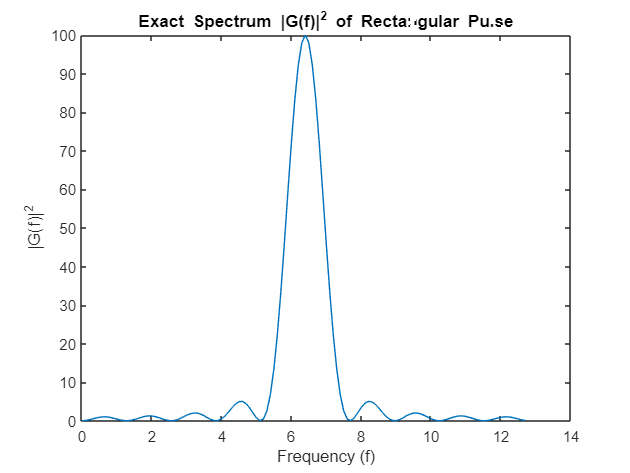

f = linspace(0, Nos-1, Nos) / 10; % Frequency values
gf = fftshift(fft(g)); % Shift the zero frequency component to the center
gf_squared = abs(gf).^2;
plot(f, gf_squared);
title('Rectangular Pulse Exact Spectrum (|G(f)|^2)');
xlabel('Frequency f');
ylabel('|G(f)|^2');

# Question 3-2

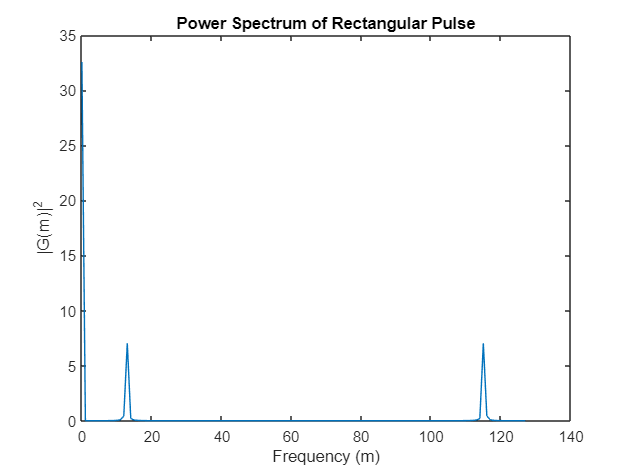

T = 1; % Pulse width
Nos = 128; % Number of samples
t = (0:Nos-1) / 10; % Time values from 0 to 12.7
g = 1/2 * (1 - cos(2 * pi * t / T));
G = fft(g);
Sv = abs(G).^2 / Nos;
m = 0:Nos-1;
plot(m, Sv);
title('Power Spectrum of Rectangular Pulse');
xlabel('Frequency (m)');
ylabel('|G(m)|^2');

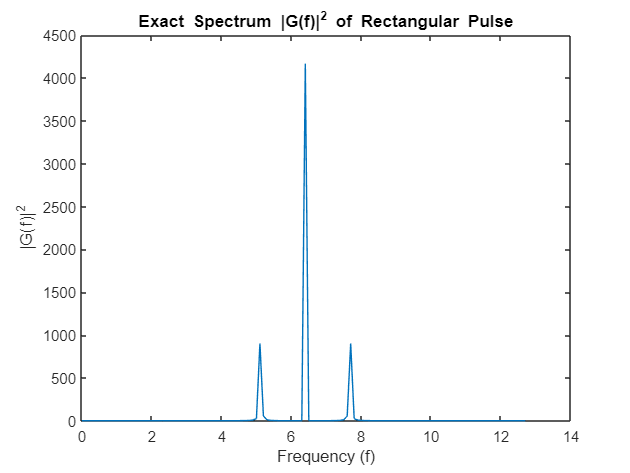

f = linspace(0, Nos-1, Nos) / 10; % Frequency values
gf = fftshift(fft(g)); % Shift the zero frequency component to the center
gf_squared = abs(gf).^2;
plot(f, gf_squared);
title('Exact Spectrum |G(f)|^2 of Rectangular Pulse');
xlabel('Frequency (f)');
ylabel('|G(f)|^2');

# Question 3-3

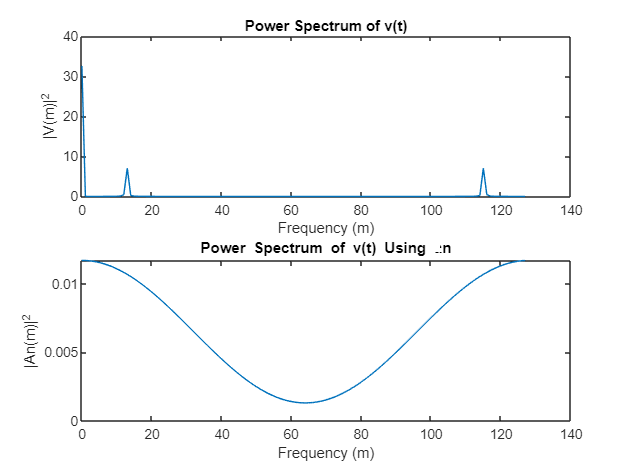

T = 1; % Pulse width
Nos = 128; % Number of samples
t = (0:Nos-1) / 10; % Time values from 0 to 12.7
g = 1/2 * (1 - cos(2 * pi * t / T)); % Pulse function

M = length(g);
Ra = zeros(1, M);
Ra(1) = 1;
Ra(2) = 1/2;
Ra(end) = 1/2;

% Generate the sequence {an}
an = Ra(1:2) / sqrt(sum(Ra(1:2)));
an = [an, zeros(1, Nos - length(an))];
V = fft(g);
Sv = abs(V).^2 / Nos;
Sv1 = abs(fft(an)).^2 / Nos;

% Plot the power spectrum
m = 0:Nos-1;
subplot(2, 1, 1);
plot(m, Sv);
title('Power Spectrum of v(t)');
xlabel('Frequency m');
ylabel('|V(m)|^2');

subplot(2, 1, 2);
plot(m, Sv1);
title('Power Spectrum of v(t) Using {an}');
xlabel('Frequency m');
ylabel('|An(m)|^2');